# Neurophysiological Data

The following report and code has been written by Charles Burns for the Computational Neuroscience course. (10/01/2024).

Guidelines and exercises provided by Ben Willmore.

## Part I: Plotting single-trial data

load 'spiketimes.mat'; %matlab daata file
% whos; %check what vairables are included and their sizes

**Q1: What kind of variable is single_trial? **

class('single_trial')

ans = 'char'

**A: **it's a double array. Sometimes referred to as a 'vector'

**Q2: How big is it?**

sz = size(single_trial) %storing the size

sz =      1    41


**A**: It's size is 1x41, meaning it's one row with 41 columns, containing 41 different numbers.

**Q3: Cut and paste the labelled raster plot into your Word document.**

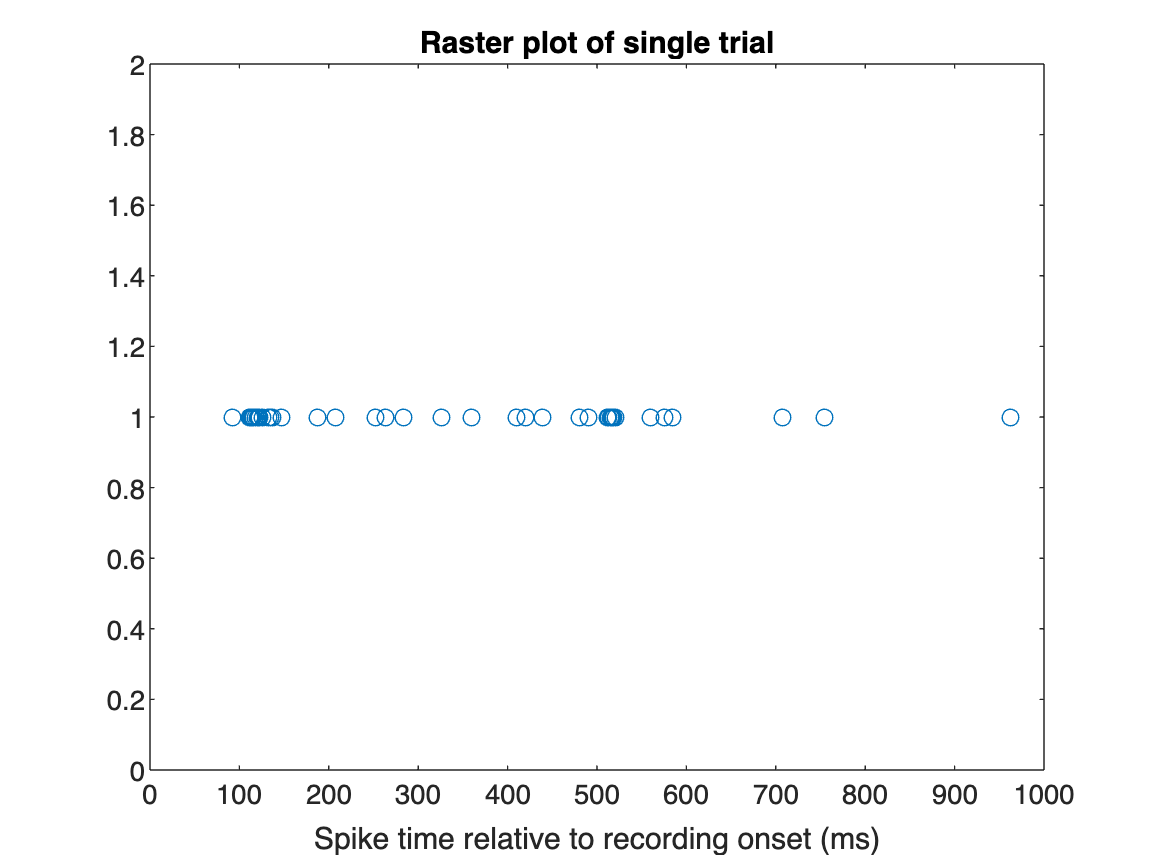

%following instructions to make a raster plot
plot(single_trial,ones(sz),'o');
xlabel('Spike time relative to recording onset (ms)')
title('Raster plot of single trial')

**Q4: Cut and paste the labelled histogram into your Word document.**

%following instructions to make a per-stimulus time histogram (PSTH)
edges = 0:10:1000;
response=histc(single_trial,edges) %count trials in each bin

response =      0     0     0     0     0     0     0     0     0     1     0     7     4     3     1     0     0     0     1     0     1     0     0     0     0     1     1     0     1     0     0     0     1     0     0     0     1     0     0     0     0     1     1     1     0     0     0     0     1     1


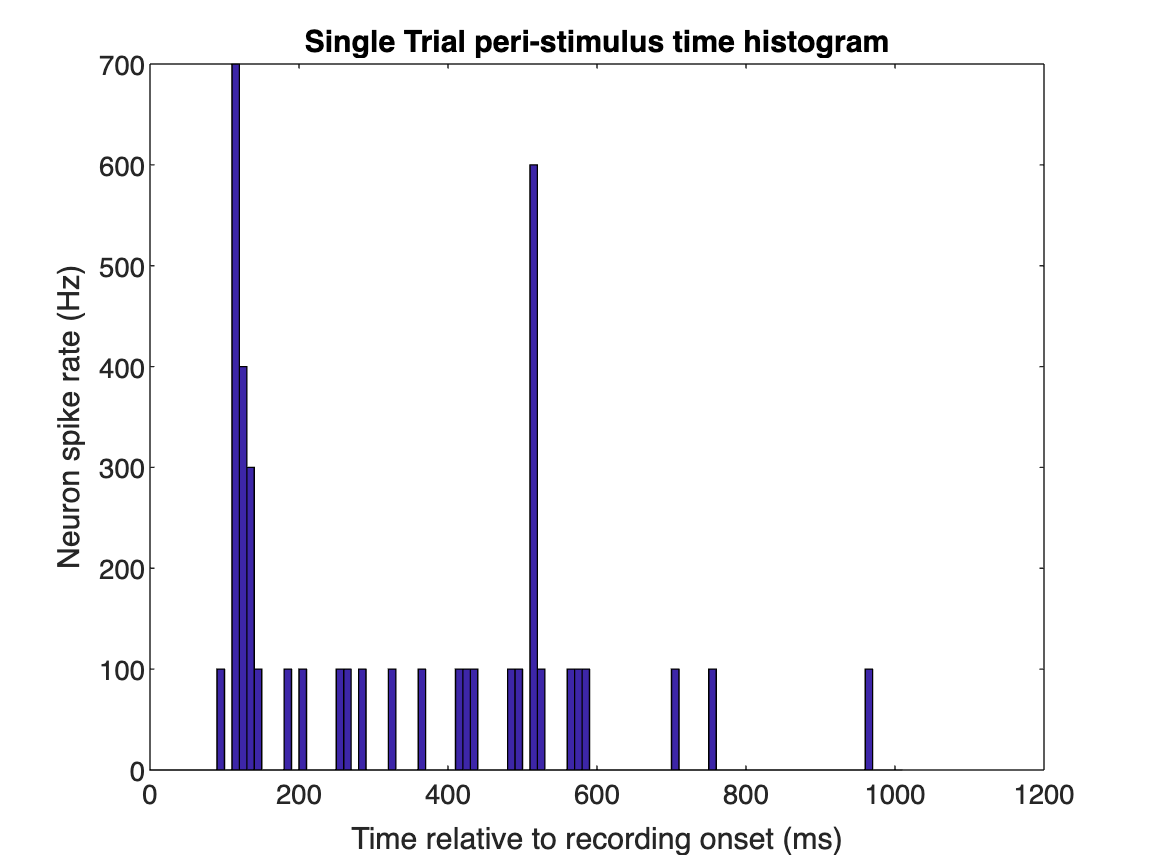

response=response/0.01; %spikes by second by scaling to length of the bin.

bar(edges,response, 'histc');
xlabel('Time relative to recording onset (ms)')
ylabel('Neuron spike rate (Hz)')
title('Single Trial peri-stimulus time histogram')

**Q5: Knowing that the stimulus onset was at 100ms, what was the response latency of the neuron, i.e., the time that the first peak in spiking occurred?**

**A**: The first peak happens between 110 and 120ms, indicated by the height of the bin in the above figure. This would suggest that the response latency of the neuron is ~15ms. 

This is a noisy estimate and may be influenced by our choice of bin edges.

**Q6: What was the maximum response rate of the neuron, in spikes/second?**

**A**: 700.

## Part II: Multiple-trial data and 'for' loops.

**Q7: Paste the figure into your Word document.**

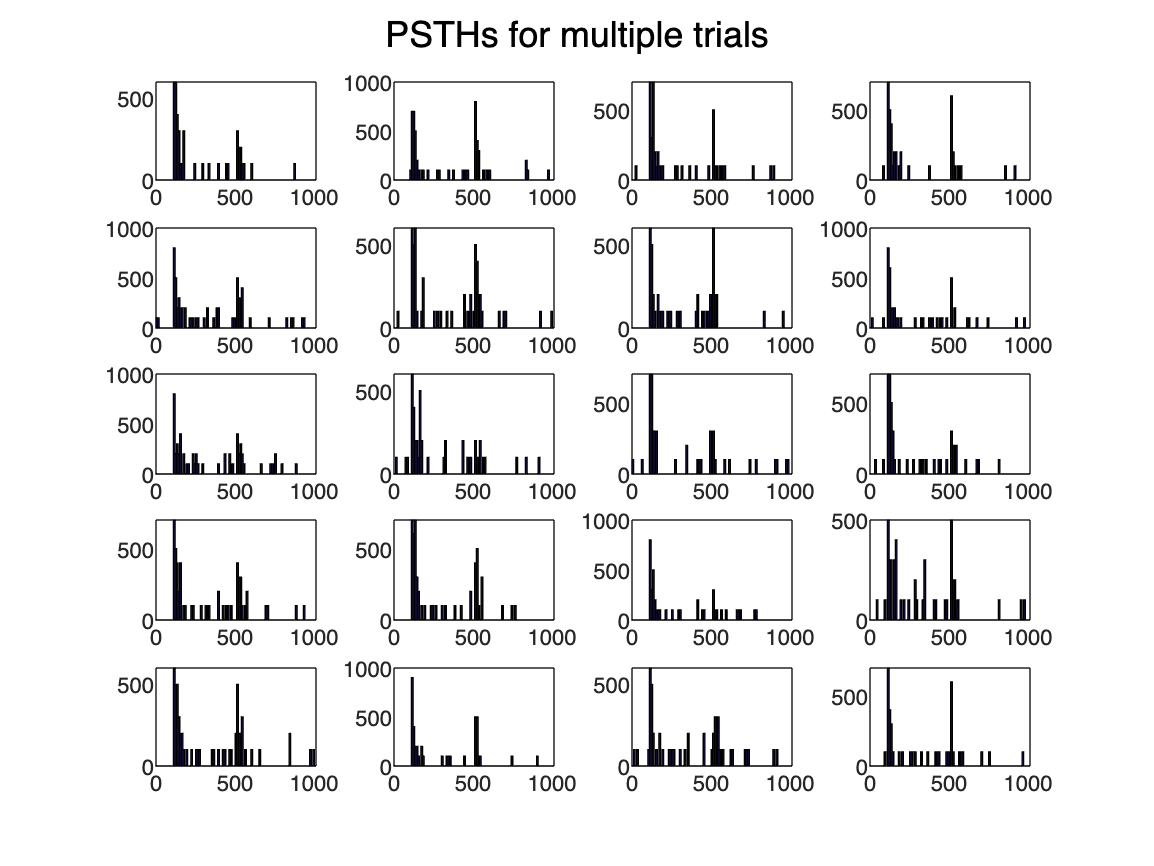

%again, following instructions (see plotpsthes.m)
plotpsthes
sgtitle('PSTHs for multiple trials')

**Q8: Paste the figure into your Word document. What does each graph represent now?**

plotpsthes2
sgtitle('Spike frequency per trial for each bin')

**A:** Each graph, for a given time bin (e.g. 0-10ms), now represents the spike frequency per trial (1-20). 

To some, it might indicate how much variability there is across trials (whether there is consistency in when neurons spikes across trials).

But 101 plots is a lot. We shouldn't really be doing this.

**Q9: Label your axes, give your figure a title and paste it into your Word document.**

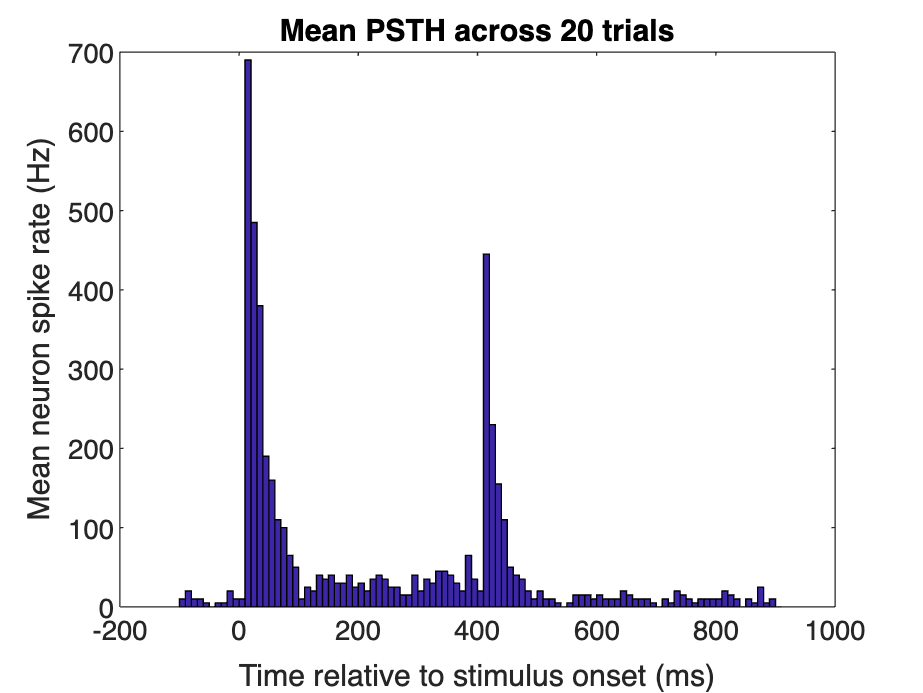

close all;

%obsolete code:
% mn = zeros(1,101);
% nTrials = size(condition1,1)
% for ii = 1:nTrials;
% 
%  mn = mn + condition1(ii,:)/0.01; %rescaling to hrz
% end
% mn = mn/nTrials; %mean per trial

bar((edges-100),mean(condition1)*100,'histc');
title('Mean PSTH across 20 trials')
xlabel('Time relative to stimulus onset (ms)')
ylabel('Mean neuron spike rate (Hz)')

## Part III: Comparing conditions

**Q10: Label your axes, give your figure a title and paste it into your Word document.**

mean1 = mean(condition1)/0.01 %rescaling to Hz

mean1 =    10.0000   20.0000   10.0000   10.0000    5.0000         0    5.0000    5.0000   20.0000   10.0000   10.0000  690.0000  485.0000  380.0000  190.0000  160.0000  110.0000  100.0000   65.0000   50.0000   10.0000   25.0000   20.0000   40.0000   35.0000   40.0000   30.0000   30.0000   40.0000   25.0000   30.0000   20.0000   35.0000   40.0000   35.0000   25.0000   25.0000   15.0000   15.0000   40.0000   20.0000   35.0000   30.0000   45.0000   45.0000   40.0000   30.0000   20.0000   65.0000   35.0000


sd1 = std(condition1)/0.01

sd1 =    30.7794   41.0391   30.7794   30.7794   22.3607         0   22.3607   22.3607   41.0391   30.7794   30.7794   96.7906  142.4411  167.3320   96.7906  118.7656  144.7321   85.8395   81.2728   60.6977   30.7794   44.4262   41.0391   59.8243   48.9360   59.8243   47.0162   47.0162   59.8243   44.4262   47.0162   41.0391   67.0820   50.2625   81.2728   55.0120   44.4262   36.6348   48.9360   68.0557   41.0391   67.0820   47.0162   68.6333   60.4805   59.8243   57.1241   41.0391   67.0820   81.2728



mean2 = mean(condition2)/0.01

mean2 =    10.0000   10.0000   15.0000   10.0000   10.0000   10.0000    5.0000   30.0000   10.0000   15.0000    5.0000  720.0000  520.0000  285.0000  205.0000  160.0000  110.0000   70.0000   40.0000   30.0000   35.0000   25.0000   40.0000   40.0000   35.0000   35.0000   25.0000   20.0000   25.0000   10.0000   25.0000   30.0000   15.0000   30.0000   25.0000   20.0000   25.0000   30.0000   35.0000   35.0000   20.0000   30.0000   50.0000   15.0000   30.0000   15.0000   40.0000   15.0000   10.0000   50.0000


sd2 = std(condition2)/0.01

sd2 =    30.7794   30.7794   48.9360   30.7794   30.7794   30.7794   22.3607   57.1241   30.7794   36.6348   22.3607   83.3509  154.2384  153.1253  105.0063  123.1174   96.7906  108.0935   59.8243   47.0162   48.9360   44.4262   59.8243   68.0557   48.9360   58.7143   55.0120   41.0391   44.4262   30.7794   55.0120   57.1241   48.9360   47.0162   55.0120   41.0391   44.4262   47.0162   48.9360   58.7143   41.0391   57.1241   68.8247   36.6348   47.0162   36.6348   50.2625   36.6348   30.7794   60.6977


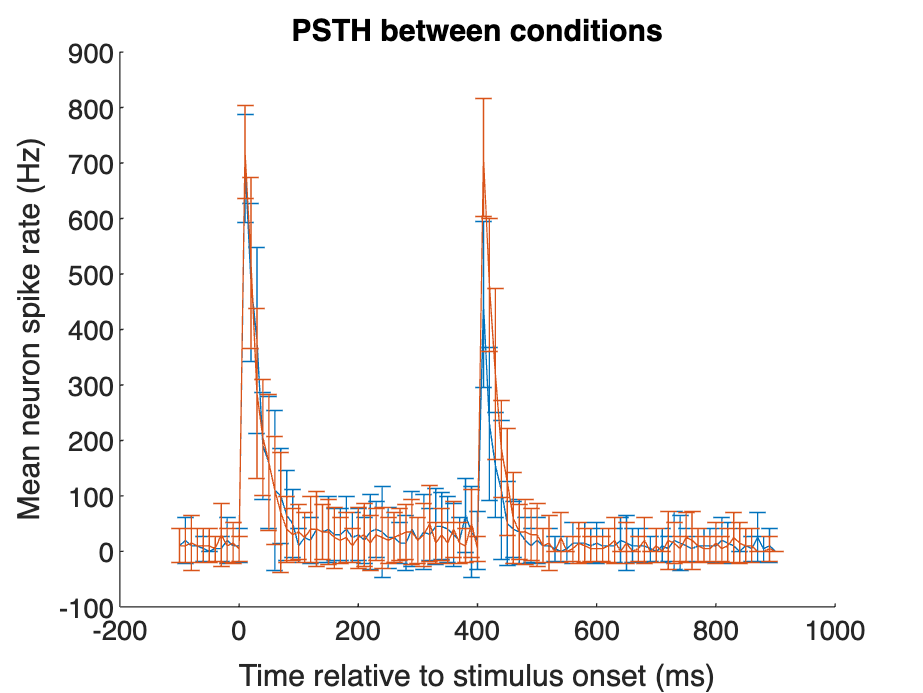


figure; hold on;
errorbar((edges-100),mean1,sd1);
errorbar((edges-100),mean2,sd2);
title('PSTH between conditions');
xlabel('Time relative to stimulus onset (ms)')
ylabel('Mean neuron spike rate (Hz)')

**Q11. Are the responses of the neuron different in the two conditions? At what time are the responses most different?**

**A: **The above figure would suggest that the neuron's responses are not different between conditions. 

whichMaxDiff = find(abs(mean2-mean1)==max(abs(mean2-mean1)))

whichMaxDiff = 52

The largest difference in spike rate is observed between 410 and 420 milliseconds after stimulus onset (510 and 520 ms after recording onset).

diffTrials1 = condition1(:,whichMaxDiff);

diffTrials2 = condition2(:,whichMaxDiff);

[h, p] = ttest2(diffTrials1,diffTrials2); %checking whether they come from distributions with equal means.

p

p = 1.5146e-07

**Q12. Are the responses significantly different at P<0.01? What about P<0.001?**

p < 0.01

ans = logical
   1


p < 0.001

ans = logical
   1


**A: **Yes to both. (we have $p < 10^{-6}$). 

## Part IV: Cell arrays

**Q13. Label your axes, give your figure a title and paste it into your Word document.**

nTrials = size(spiketimes1,2)

nTrials = 20

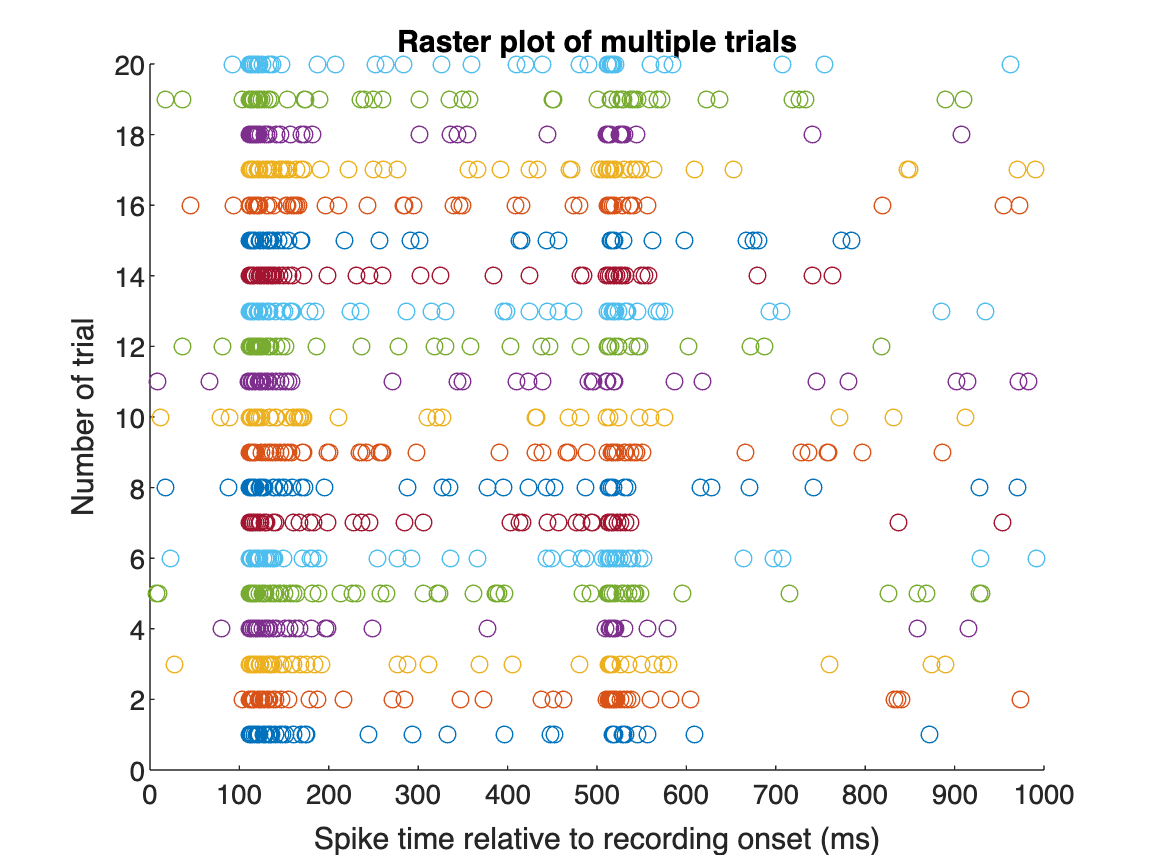


figure; hold on;
for i= 1:nTrials
sz= size(spiketimes1{i});
%following instructions to make a raster plot
plot(spiketimes1{i},ones(sz)*i,'o');
xlabel('Spike time relative to recording onset (ms)')
ylabel('Number of trial')
title('Raster plot of multiple trials')
end
hold off;

**Q14. Label your axes, give your figure a title and paste it into your Word document.**

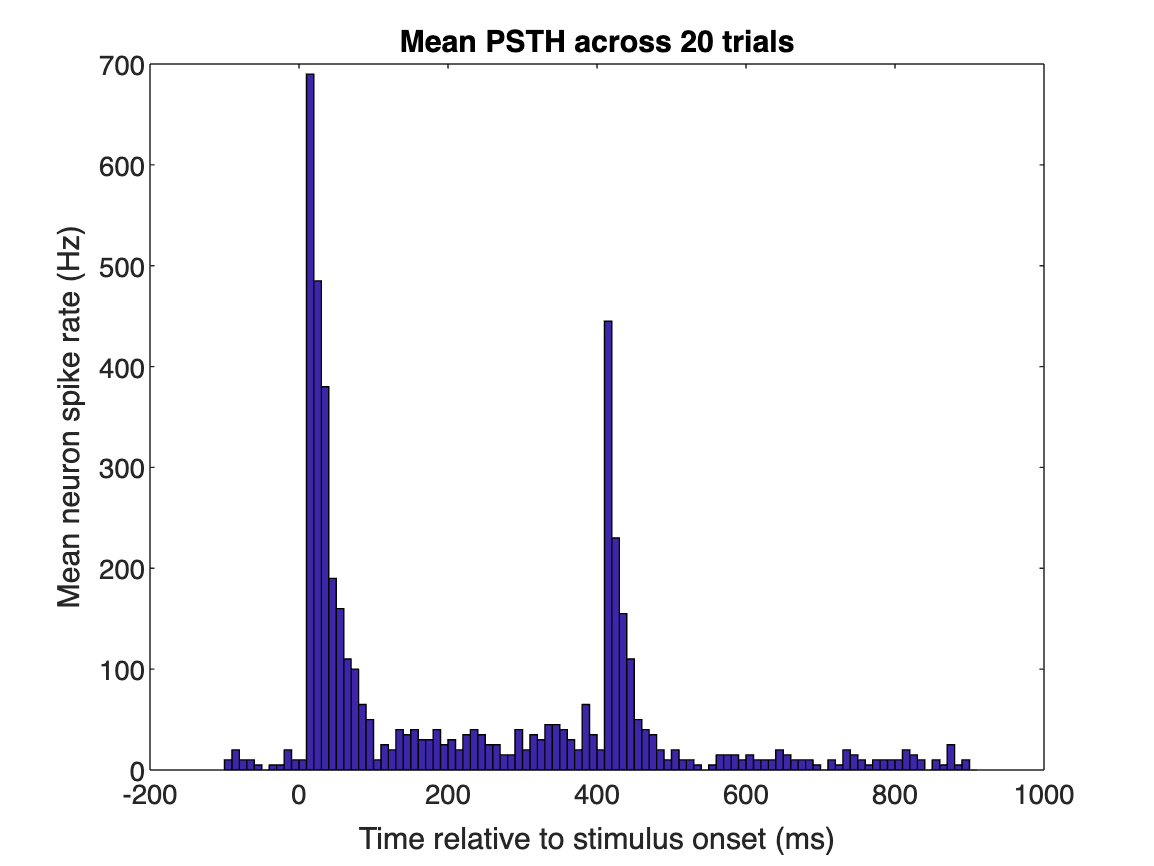

allTrialData = [spiketimes1{:}];
nTrials = size(spiketimes1,2);
edges = 0:10:1000;
response=histc(allTrialData,edges); %count trials in each bin
response=response/0.01; %spike Hz second by scaling to length of the bin.
meanResponse = response/nTrials;

bar((edges-100),meanResponse, 'histc');
xlabel('Time relative to stimulus onset (ms)')
ylabel('Mean neuron spike rate (Hz)')
title('Mean PSTH across 20 trials')